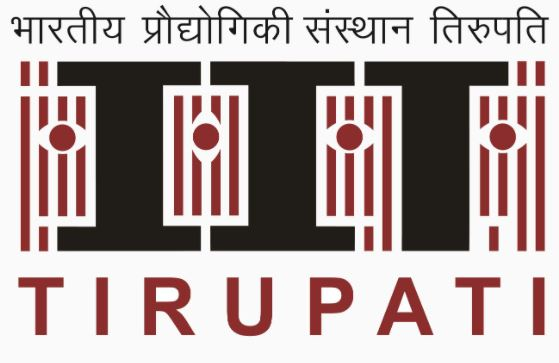

### **Digital Signal Processing Laboratory**

**LabSheet-02**

Name: Suriyaa MM

Roll Number: EE23B054

### Convolution and it's Properties

#### A. Implementation of Convolution

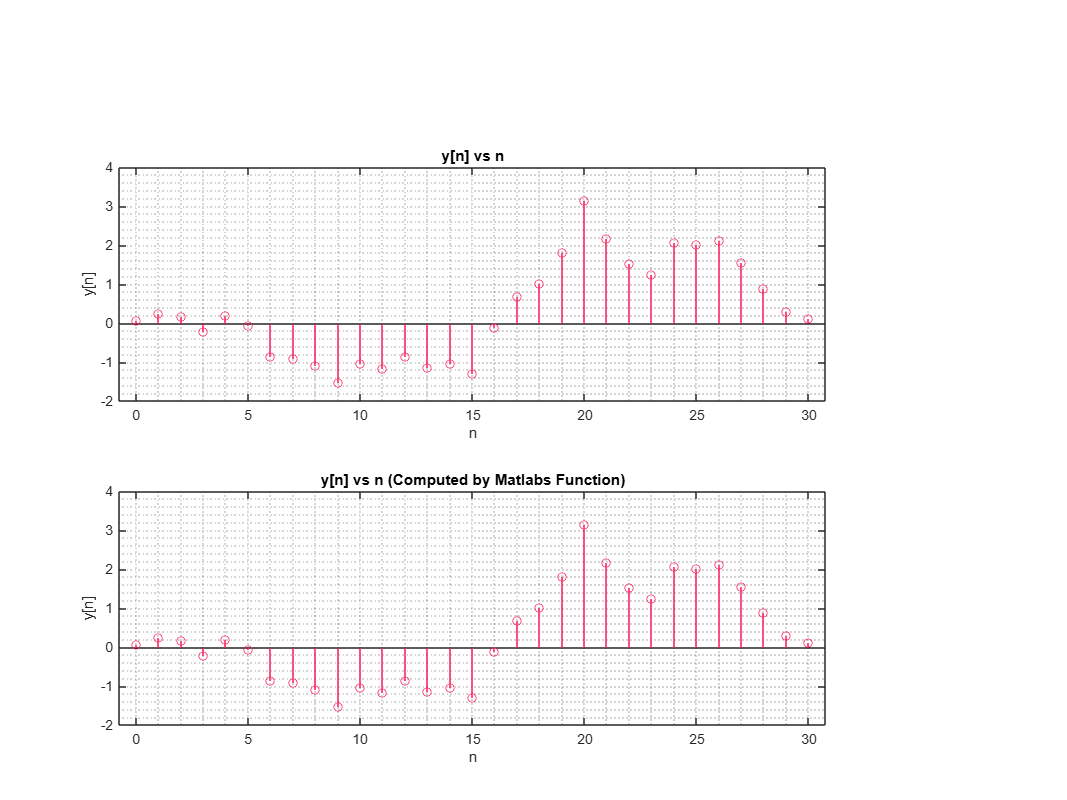

COLOUR_1 = "#fc1758";
COLOUR_2 = "#cc25e6";
COLOUR_3 = "#f533b4";
COLOUR_4 = "#fc8d17";
COLOUR_5 = "#c4a484";
COLOUR_6 = "#332A28";
COLOUR_7 = "#4a8af0";
COLOUR_BLACK = "#ffffff";

function y = conv_ee23b054(M, N, a, b, c, d)
    % Function to compute the convolution of two sequences manually
    % Inputs:
    %   M: Length of impulse response sequence - 1
    %   N: Length of input sequence - 1
    %   a, b: Range for uniform distribution of h[n]
    %   c, d: Range for uniform distribution of x[n]
    % Output:
    %   y: Convolution result of x and h
    
    % Generate random impulse response sequence h[n]
    h = (b - a) * rand(M + 1, 1) + a;
    
    % Generate random input sequence x[n]
    x = (d - c) * rand(N + 1, 1) + c;
    
    % Initialize the output sequence y with zeros
    y = zeros(N + M + 1, 1);
    
    % Compute the convolution manually
    for i = 1:(N + 1)
        for j = 1:(M + 1)
            if (i + j - 1 <= N + M + 1)
                y(i + j - 1) = y(i + j - 1) + x(i) * h(j);
            end
        end
    end

    inbuilt_conv = conv(x,h);
    n = linspace(0, (N+M),(N+M+1));
    
    figure;
    figProps = gcf;
    figProps.Position(3:4) = figProps.Position(3:4) * 2;
    
    subplot(2,1,1);
    stem(n, y, Color = "#fc1758");
    xlabel('n');
    ylabel('y[n]');
    title('y[n] vs n');
    
    set(gca, "XMinorGrid", "on");
    set(gca, "YMinorGrid", "on");

    subplot(2,1,2);
    stem(n, inbuilt_conv, Color = "#fc1758");
    xlabel('n');
    ylabel('y[n]');
    title('y[n] vs n (Computed by Matlabs Function)');
    
    set(gca, "XMinorGrid", "on");
    set(gca, "YMinorGrid", "on");

end

M = 10;  
N = 20;  
a = 0; b = 1;  
c = -1; d = 1; 

conv_ee23b054(M, N, a, b, c, d);

Thus we can conclude that our convolution function is working properly.

#### B. Systems in Parallel

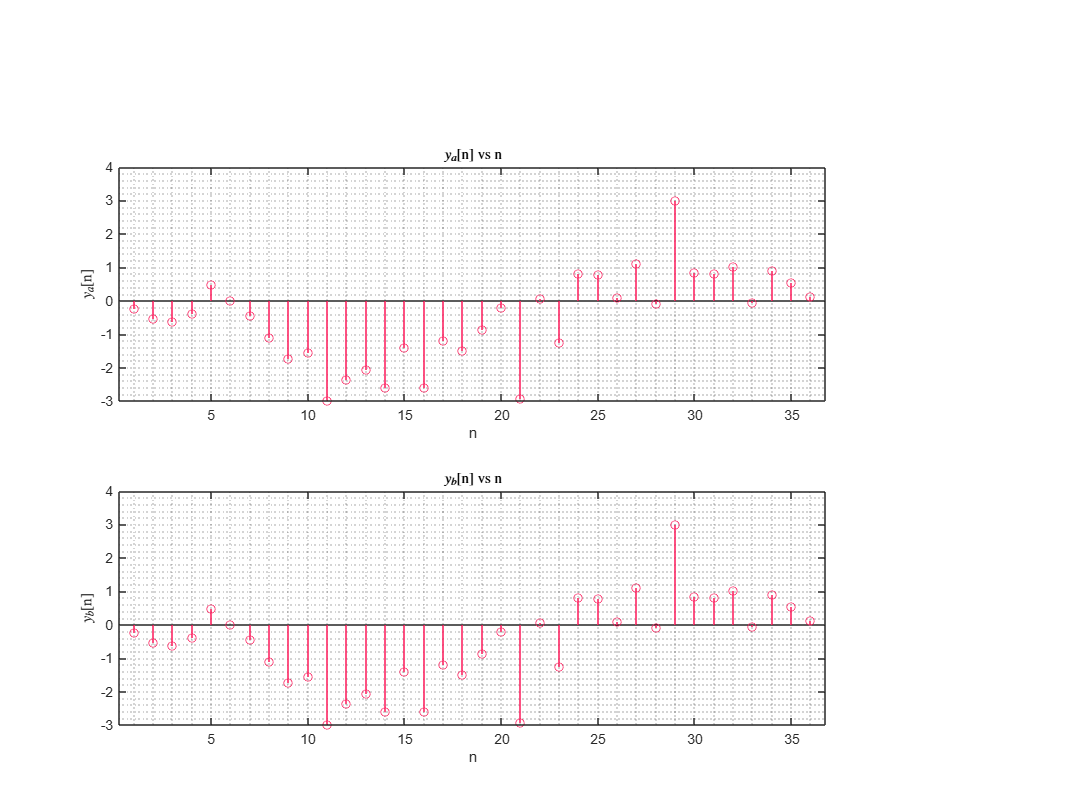

M1 = 10; M2 = 15;

% Generate random impulse response sequence h1[n]
h1 = (b - a) * rand(M1 + 1, 1) + a;

% Generate random impulse response sequence h2[n]
h2 = (b - a) * rand(M2 + 1, 1) + a;

% Generate random input sequence x[n]
x = (d - c) * rand(N + 1, 1) + c;

% Compute y1[n] = x[n] * h1[n]
y1 = conv(x, h1);

% Compute y2[n] = x[n] * h2[n]
y2 = conv(x, h2);
    
% Determine the maximum length
max_len = max(length(y1), length(y2));
    
% Pad y1 and y2 with zeros to match the maximum length
y1_padded = [y1; zeros(max_len - length(y1), 1)];
y2_padded = [y2; zeros(max_len - length(y2), 1)];
    
% Add the padded convolutions
ya = y1_padded + y2_padded;

max_len = max(length(h1), length(h2));

% Pad impulse responses to match the length of the input sequence
h1_padded = [h1; zeros(max_len - length(h1), 1)];
h2_padded = [h2; zeros(max_len - length(h2), 1)];
    
% Compute the sum of the padded impulse responses
h_padded = h1_padded + h2_padded;
    
% Compute the convolution with the summed impulse response
yb = conv(x, h_padded);

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 2;
    
subplot(2,1,1);
stem(ya, Color = "#fc1758");
xlabel('n');
ylabel('$y_a$[n]', Interpreter = "latex");
title('$y_a$[n] vs n', Interpreter = "latex");
    
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,1,2);
stem(yb, Color = "#fc1758");
xlabel('n');
ylabel('$y_b$[n]', Interpreter = "latex");
title('$y_b$[n] vs n', Interpreter = "latex");
   
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

#### C. Systems in Cascade

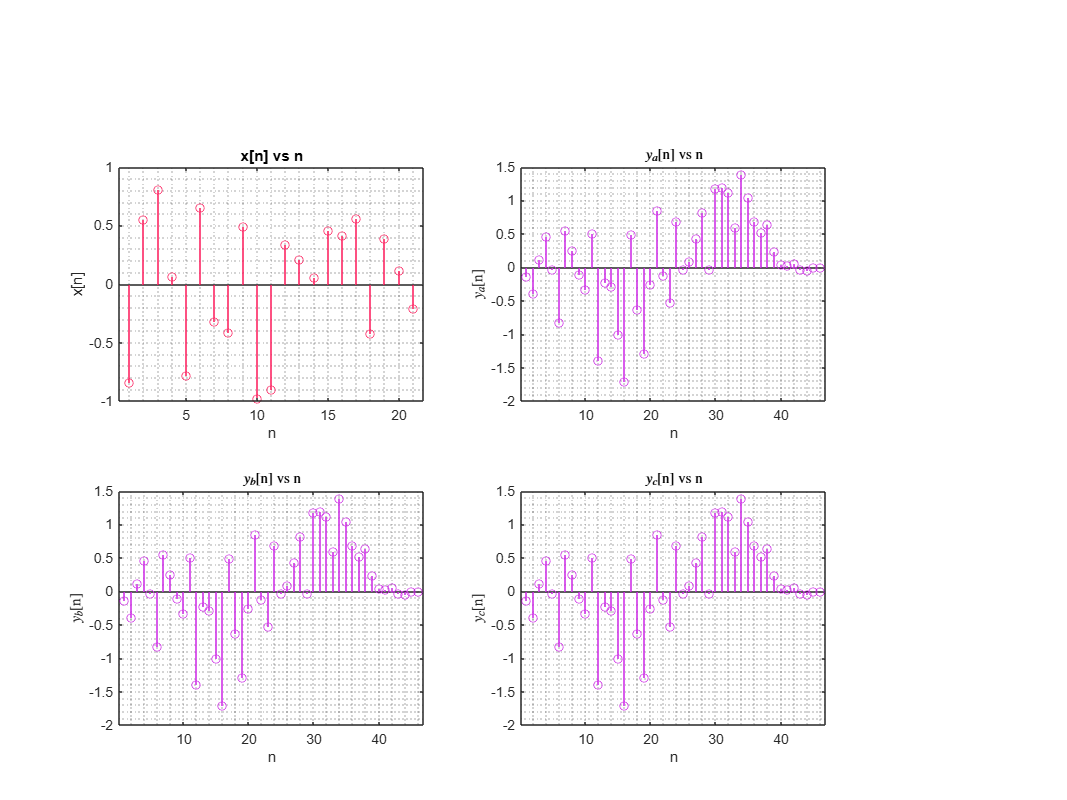

M1 = 10; M2 = 15;

% Generate random impulse response sequence h1[n]
h1 = (b - a) * rand(M1 + 1, 1) + a;

% Generate random impulse response sequence h2[n]
h2 = (b - a) * rand(M2 + 1, 1) + a;

% Generate random input sequence x[n]
x = (d - c) * rand(N + 1, 1) + c;

% Computation of ya
x1 = conv(x, h1);
ya = conv(x1, h2);

% Computation of yb
x1 = conv(x, h2);
yb = conv(x1, h1);

% Computation of yc
h = conv(h1, h2);
yc = conv(x, h);

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 4;
    
subplot(2,2,1);
stem(x, Color = COLOUR_1);
xlabel('n');
ylabel('x[n]');
title('x[n] vs n');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,2);
stem(ya, Color = COLOUR_2);
xlabel('n');
ylabel('$y_a$[n]', Interpreter = "latex");
title('$y_a$[n] vs n', Interpreter = "latex");
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,3);
stem(yb, Color = COLOUR_2);
xlabel('n');
ylabel('$y_b$[n]', Interpreter = "latex");
title('$y_b$[n] vs n', Interpreter = "latex");
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,4);
stem(yc, Color = COLOUR_2);
xlabel('n');
ylabel('$y_c$[n]', Interpreter = "latex");
title('$y_c$[n] vs n', Interpreter = "latex");
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

We can clearly see from the figure that ya, yc, yb are the same.

#### D. Conjugate Symmetry of Fourier Transform

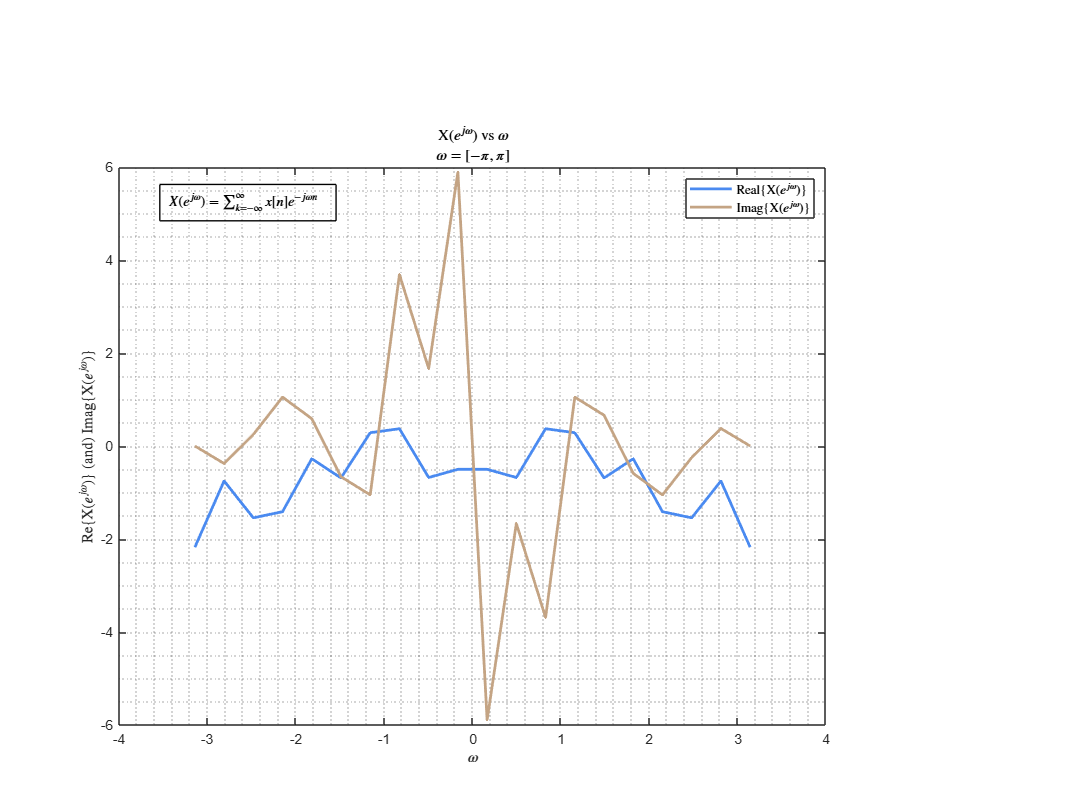

function X_w = fourierTransform(x_n, w)

N = length(x_n);
% Initialize the output array
X_w = zeros(size(w));

% Compute the Fourier transform using the summation formula
for k = 1:length(w)
    for n = 1:N
        X_w(k) = X_w(k) + x_n(n) * exp(-1j * w(k) * (n - 1));
    end
end
end

COLOUR_1 = "#fc1758";
COLOUR_2 = "#cc25e6";
COLOUR_3 = "#f533b4";
COLOUR_4 = "#fc8d17";
COLOUR_5 = "#c4a484";
COLOUR_6 = "#332A28";
COLOUR_7 = "#4a8af0";
COLOUR_BLACK = "#ffffff";

n = 20;
C = 0; D = 1;
w = linspace(-pi, pi, n);

x_n = C + (D - C) .* rand(1, n);
X_w = fourierTransform(x_n, w);

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 2;

plot(w, real(X_w), Color = COLOUR_7, LineWidth = 2);
xlabel('$\omega$', 'Interpreter', 'latex'); 
ylabel('Re\{X($e ^ {j \omega}$)\} (and) Imag\{X($e ^ {j \omega})$\}', Interpreter = 'latex');
title('X($e ^ {j \omega})$ vs  $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

hold on;
plot(w, imag(X_w), Color = COLOUR_5, LineWidth = 2);
annotation('textbox', [0.175, 0.8, 0.1, 0.1], "String", '$X(e^{j \omega}) = \sum_{k = -\infty}^{\infty}x[n] e^{-j \omega n}$', 'FitBoxToText', 'on', 'Interpreter', 'latex');
legend({'Real\{X($e ^ {j \omega})$\}', 'Imag\{X($e ^ {j \omega})$\}'}, Interpreter="latex");

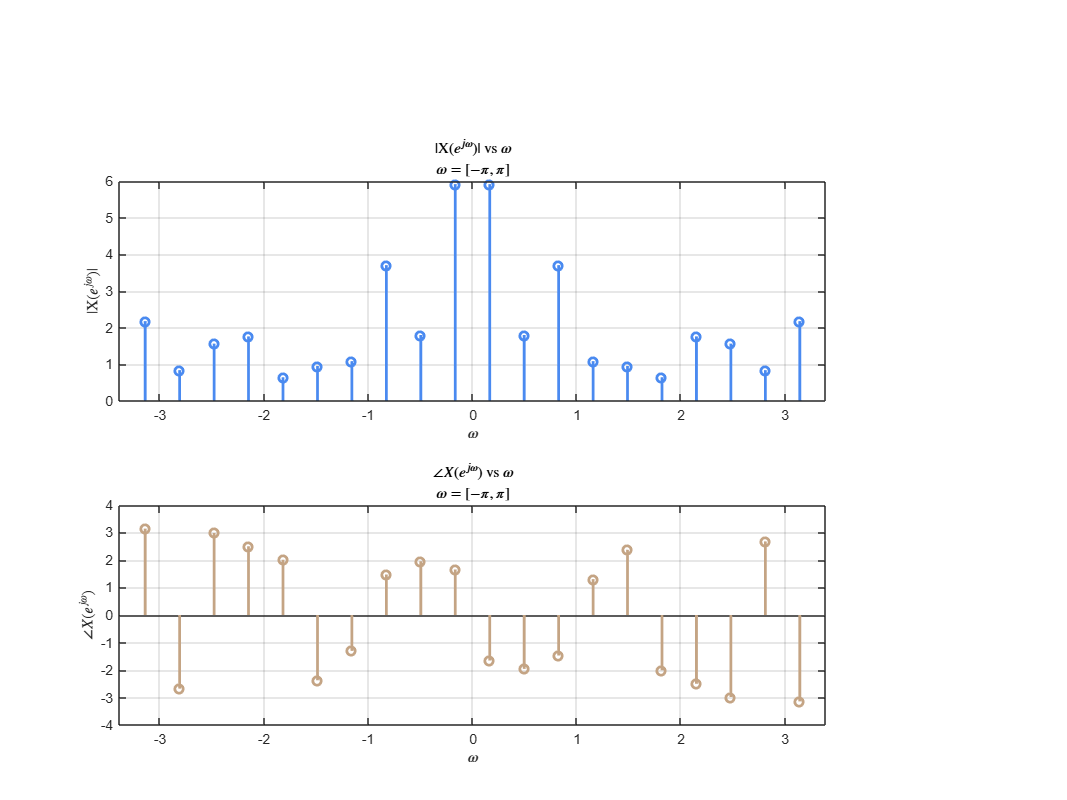


figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 2;

subplot(2, 1, 1);
stem(w, abs(X_w), Color = COLOUR_7, LineWidth = 2);
xlabel('$\omega$', Interpreter = 'latex'); 
ylabel('|X($e ^ {j \omega})$|', Interpreter = 'latex');
title('|X($e ^ {j \omega})$| vs  $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = "latex");
grid("on");


subplot(2, 1, 2);
stem(w, angle(X_w), Color = COLOUR_5, LineWidth = 2);
xlabel('$\omega$', Interpreter = 'latex'); 
ylabel('$\angle X(e ^ {j \omega})$', Interpreter = 'latex');
title('$\angle X(e ^ {j \omega})$ vs  $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = "latex");
grid("on");

We can clearly see from the graph that Real part of $$Real\{X(e ^ {j \omega})\}$$ is even symmetric about origin and $$Imag\{X(e ^ {j \omega})\}$$ is odd symmetric about origin.

We can see $$|\{X(e ^ {j \omega})\}|$$ is even symmetric about origin and $$\angle \{X(e ^ {j \omega})\}$$ is odd symmetric about origin.

### 3. Fourier Transform of Even and Odd Signals

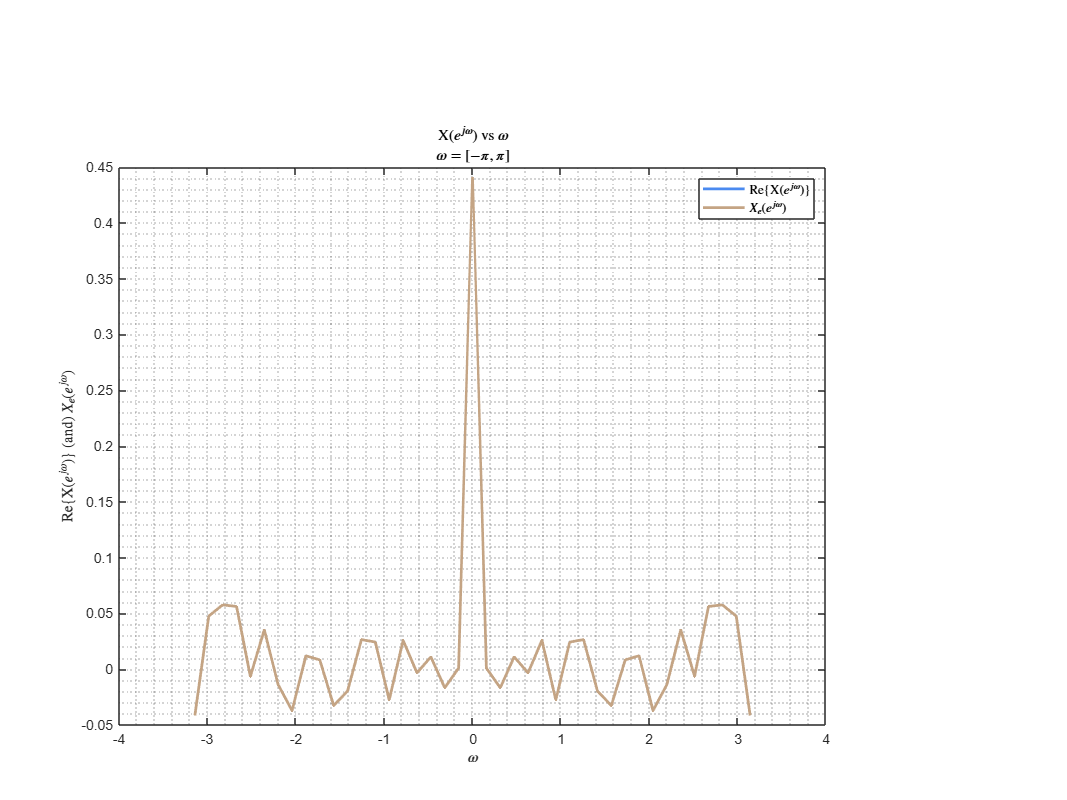

N = 20;
C = 0; D = 1;
n = -N:N;
w = linspace(-pi, pi, length(n));
x_n = C + (D - C) .* rand(1, length(n));

x_e_n = 0.5 * (x_n + fliplr(x_n));

X_w = fourierTransform(x_n, w);
Xe_w = fourierTransform(x_e_n, w);

X_w = X_w / length(x_n);
Xe_w = Xe_w / length(x_e_n);

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 2;

plot(w, real(X_w), Color = COLOUR_7, LineWidth = 2);
xlabel('$\omega$', 'Interpreter', 'latex'); 
ylabel('Re\{X($e ^ {j \omega}$)\} (and) $X_e$($e ^ {j \omega})$', Interpreter = 'latex');
title('X($e ^ {j \omega})$ vs  $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

hold on;
plot(w, real(Xe_w), Color = COLOUR_5, LineWidth = 2);
legend({'Re\{X($e ^ {j \omega}$)\}', '$X_e$($e ^ {j \omega}$)'}, Interpreter = 'latex');

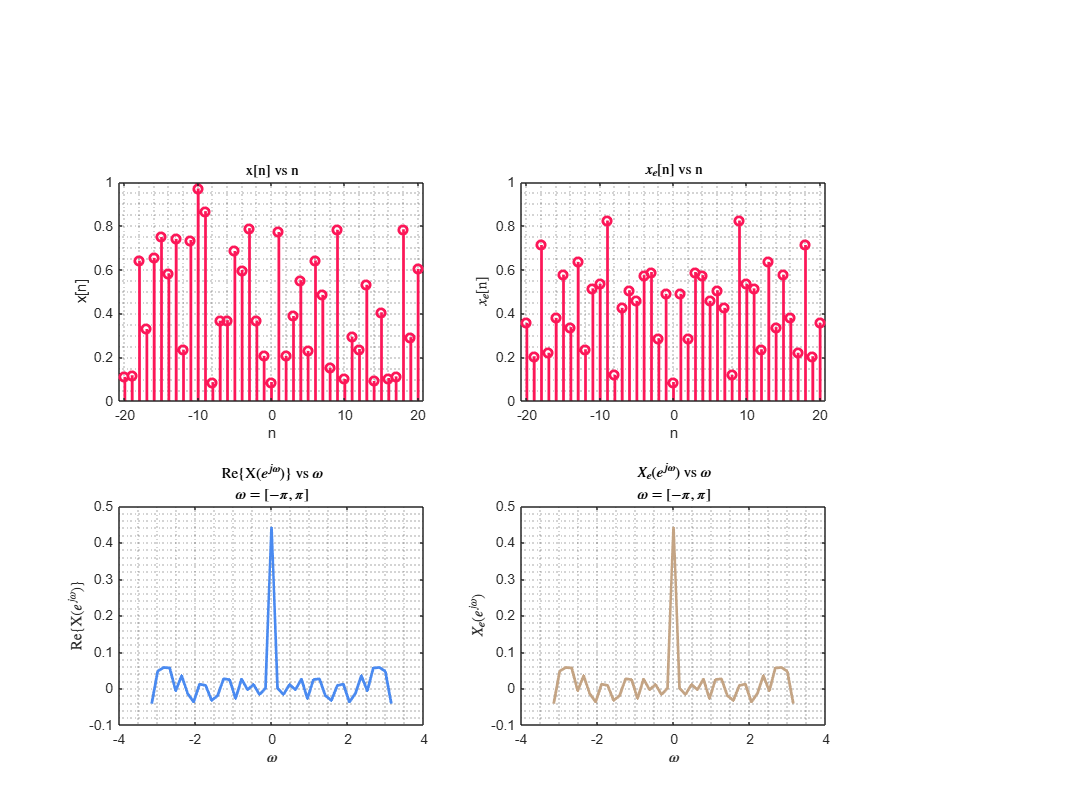


figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 4;

subplot(2,2,1);
stem(n, x_n, Color = COLOUR_1, LineWidth = 2);
xlabel('n');
ylabel('x[n]');
title('x[n] vs n', Interpreter = "latex");
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,2);
stem(n, x_e_n, Color = COLOUR_1, LineWidth = 2);
xlabel('n');
ylabel('$x_e$[n]', Interpreter = "latex");
title('$x_e$[n] vs n', Interpreter = "latex");
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,3);
plot(w, real(X_w), Color = COLOUR_7, LineWidth = 2);
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('Re\{X($e ^ {j \omega}$)\}', Interpreter = 'latex');
title('Re\{X($e ^ {j \omega})$\} vs $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,4);
plot(w, real(Xe_w), Color = COLOUR_5, LineWidth = 2);
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$X_e$($e ^ {j \omega}$)', Interpreter = 'latex');
title('$X_e$($e ^ {j \omega})$ vs $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

We can clearly see from the graph that Real part of $$Real\{X(e ^ {j \omega})\}$$ and $$\{X_e(e ^ {j \omega})\}$$  are the same. They both got coincided in the same plot.

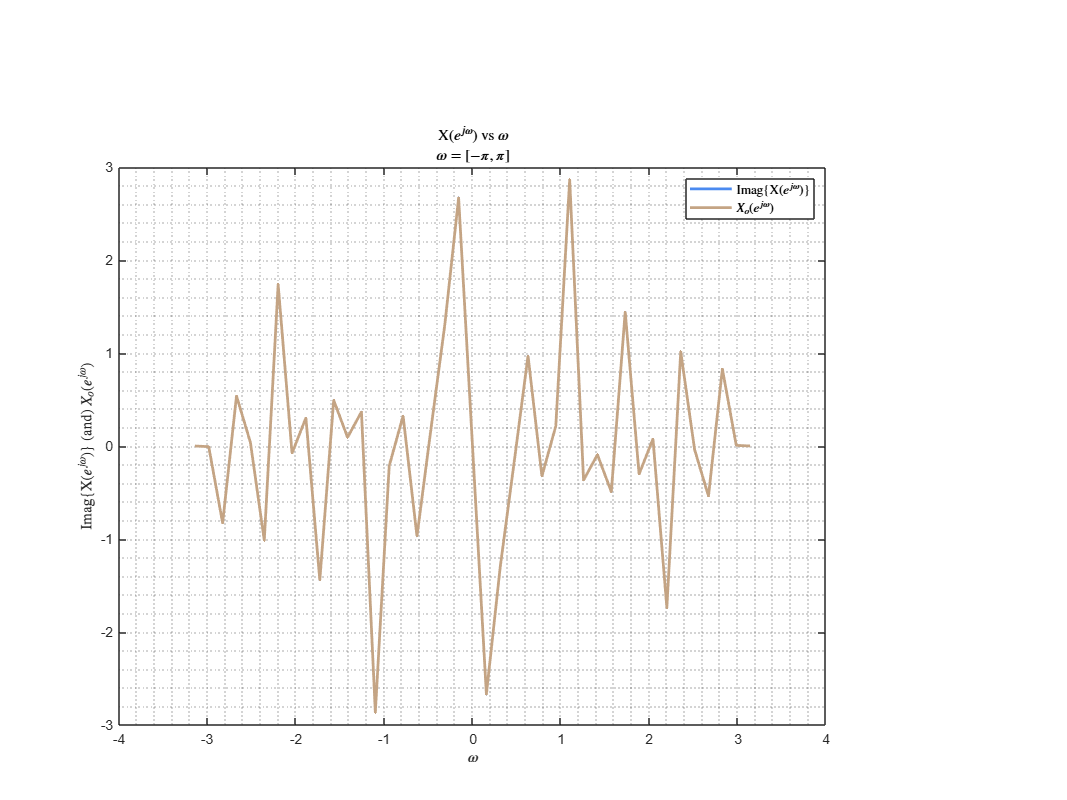

xo_n = (x_n - fliplr(x_n)) / 2;

X_w = fourierTransform(x_n, w);
Xo_w = fourierTransform(xo_n, w);

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 4;

plot(w, imag(X_w), Color = COLOUR_7, LineWidth = 2);
xlabel('$\omega$', 'Interpreter', 'latex'); 
ylabel('Imag\{X($e ^ {j \omega}$)\} (and) $X_o$($e ^ {j \omega})$', Interpreter = 'latex');
title('X($e ^ {j \omega})$ vs  $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

hold on;
plot(w, imag(Xo_w), Color = COLOUR_5, LineWidth = 2);
legend({'Imag\{X($e ^ {j \omega}$)\}', '$X_o$($e ^ {j \omega}$)'}, Interpreter = 'latex');

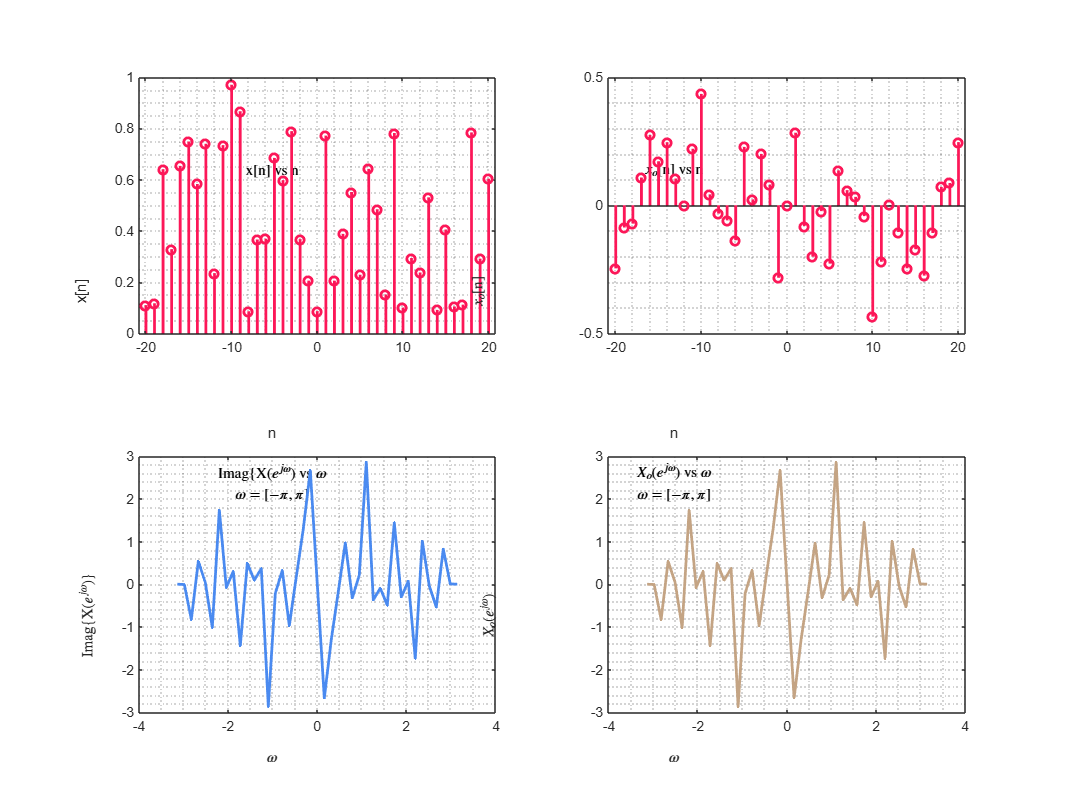


figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 4;

subplot(2,2,1);
stem(n, x_n, Color = COLOUR_1, LineWidth = 2);
xlabel('n');
ylabel('x[n]');
title('x[n] vs n', Interpreter = "latex");
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,2);
stem(n, xo_n, Color = COLOUR_1, LineWidth = 2);
xlabel('n');
ylabel('$x_o$[n]', Interpreter = "latex");
title('$x_o$[n] vs n', Interpreter = "latex");
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,3);
plot(w, imag(X_w), Color = COLOUR_7, LineWidth = 2);
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('Imag\{X($e ^ {j \omega}$)\}', Interpreter = 'latex');
title('Imag\{X($e ^ {j \omega})$ vs $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

subplot(2,2,4);
plot(w, imag(Xo_w), Color = COLOUR_5, LineWidth = 2);
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$X_o$($e ^ {j \omega}$)', Interpreter = 'latex');
title('$X_o$($e ^ {j \omega})$ vs $\omega$', Interpreter = 'latex');
subtitle('$\omega = [-\pi, \pi]$', Interpreter = 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");

We can clearly see from the graph that Real part of $$Imag\{X(e ^ {j \omega})\}$$ and $$\{X_o(e ^ {j \omega})\}$$  are the same. They both got coincided in the same plot.